clc; clear; close all;

addpath('funkcje_prowadzacej');

copyfile('dane1_wah_grupa4.mat','dane1_wah_grupa1.mat','f');

%% Setup - punkt 2
load('dane1_wah_grupa4.mat');
time = dane1.t;
sampleTime = mean(diff(time));
input = dane1.um;
xRef = dane1.ym(:,1);
phiRef = dane1.ym(:,2);

%% Setup - punkt 3
lambda0 = [0.4 0.1 0.35];
lb = [1e-6 1e-6 1e-6];
ub = [2 1 1];

%% Identyfikacja parametrow - punkt 4
fOFRV = @(lambda) fObjectiveFunctionReturnVector(lambda,xRef,phiRef);
[wynik1,resnorm] = lsqnonlin(fOFRV,lambda0,lb,ub);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



%% Identyfikacja parametrow - punkt 5
fOFRS = @(lambda) fObjectiveFunctionReturnScalar(lambda,xRef,phiRef);
[wynik2,fval] = fmincon(fOFRS,lambda0,[],[],[],[],lb,ub);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


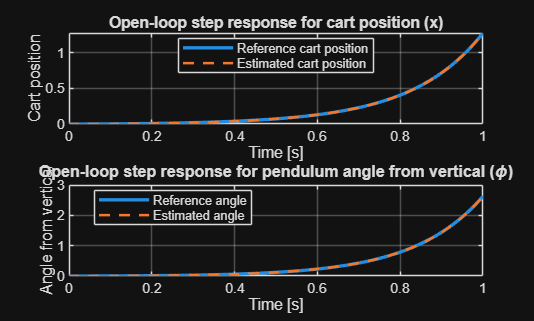



%% Odpowiedz modelu - punkt 6
[x1,phi1] = fSimulateModel(wynik1(1),wynik1(2),wynik1(3));
[x2,phi2] = fSimulateModel(wynik2(1),wynik2(2),wynik2(3));

fPlotResponseComparison(wynik1(1),wynik1(2),wynik1(3));

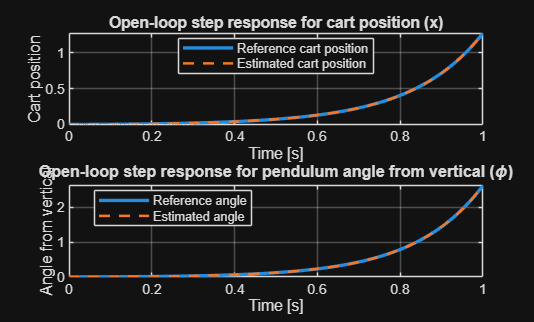

fPlotResponseComparison(wynik2(1),wynik2(2),wynik2(3));


%% Porownanie wynikow - punkt 6
T = table({'lsqnonlin';'fmincon'}, ...
    [wynik1(1);wynik2(1)], ...
    [wynik1(2);wynik2(2)], ...
    [wynik1(3);wynik2(3)], ...
    [resnorm;fval], ...
    'VariableNames',{'Metoda','m','l','I','J'})

T = 2×5 table
       Metoda           m          l          I            J     
    _____________    _______    _______    ________    __________

    {'lsqnonlin'}          1        0.7       0.026    3.1823e-13
    {'fmincon'  }    0.99998    0.70001    0.025997    1.5294e-10
